# **TP3 CMSI : EIGENVAL/VECTOR STUFF**

On va implementer une methode en particulier pour trouver les eigenvalues et eigenvectors d'une matrice A. Pour cela, il faut alterner entre deux fonctions : la puissance itérée, et la déflation de Wielandt. La première permet de trouver la eigenval de plus grand module et son eigenvec associé. La déflation permet, à partir d'une eigenvalue, d'extraire la suivante etc. jusqu'à trouver toutes les eigenval (et leur eigenvec) d'une matrice.

Dans cette partie, il faut absolument avoir des matrices CARREES.

Pour partir de la eigenval avec le plus petit module, il suffit de considérer l'inverse de A et la eigenval sera 1/(eigenval_avec_puissance_itérée_correspondant_à_inv(A)).

Juste comme ça, on rappelle la relation pour une eigenval : $\forall \vec v \in {\rm I\!R} : A\vec v  = \lambda \vec v $, avec A la matrice et $\lambda$ une eigenval (et du coup $\vec v$un eigenvec associé à $\lambda$). Aussi, tous les vecteurs portés sur la même droite sont eigenvec au *même titre*. C'est uniquement la *direction* qui importe.

#### Programmation de puissance itérée + déflation de Wielandt

Pour checker que ce qu'on a fait c'est pas de la merde, on compare avec les résultats donnés par la fonction Matlab eig().

**Puissance itérée** permet de se rapprocher peu à peu d'un eigenvec. On doit donc checker avec le dot product que le vecteur considéré et le eigenvec sont colinéaires (à une precision définie près). La norme du eigenvec n'importe pas, uniquement sa direction. Dans notre cas, on retournera la eigenval de plus grand module lambda, ainsi qu'un eigenvec normé associé.

precision = 1e-5;
A = [2 1 1 ; 1 2 1 ; 1 1 2];
[V,D] = eig(A) % ca retourne en colonne les eigenvec et une matrice diag avec les eigenval

V =     0.4082    0.7071    0.5774
    0.4082   -0.7071    0.5774
   -0.8165         0    0.5774


D =     1.0000         0         0
         0    1.0000         0
         0         0    4.0000


[X,lambda] = puissanceIt(A,precision)

X =     0.5774
    0.5774
    0.5773


lambda = 4.0000

La **déflation de Wielandt** va transformer la matrice A et enlever la eigenval avec le plus grand module, puis va appeler puissance itérée, pour trouver toutes les eigenval de la matrice. Cependant, en appelant cette fonction, on suppose qu'il reste au moins une eigenval à déterminer.

for i = 1 : size(A,1) - 1 % -1 pcq on a deja trouvé une eigenval en appelant puissanceIt
    [Y,lambda2,A] = wielandt(A,precision)
end

Y =     0.4039
   -0.8165
    0.4126


lambda2 = 1.0000

A =     0.6667   -0.3333   -0.3333
   -0.3333    0.6667   -0.3333
   -0.3333   -0.3333    0.6667


Y =    -0.5147
    0.8063
   -0.2916


lambda2 = 1.0000

A =    -1.5891   -0.7917    2.3808
    2.4895    1.2402   -3.7297
   -0.9003   -0.4485    1.3489


Du coup tout ça pour test que puissanceIt et Wielandt marche bien :)

#### Application tambour

Les vibrations sur la peau d'un tambour produisent une certaine sonorité. On cherche à étudier ces vibrations. On cherche donc à retrouver toutes les standing waves qui se superposeraient si on prenait une photo à un instant t (les souvenirs du s4 :)).

Pour ça, on suppose que la peau du tambour est tendue, rectangulaire et clouée à certains endroits. Sur la figure 6, les zones qui ne sont pas en gras sont donc susceptibles de *varier* en altitude.

Tous les points du tambour (altitudes dans vecteur U) verifient le laplacien $\Delta U = -\lambda U$. On a donc des zones où la courbure est max (alt > 0 ET/OU < 0 si elle a franchit une altitude = 0).

On peut modéliser ça avec $AU = -\lambda U$et les coefs du TP2, avec U eigenvec associé à la eigenval λ. Ainsi, on peut aussi modéliser les standing waves.

Pour trouver les eigenval de plus petit module, il suffit de faire 80x la boucle en considérant l'inverse de A (mais ca peut amener à certaines erreurs apparement). *Le temps d'execution est long, faut pas prendre peur.*

les 25 plus hautes freq sont : 
  Columns 1 through 10

    7.9504    7.9526    7.9028    7.8832    7.8756    7.8742    7.8566    7.8172    7.8103    7.7907

  Columns 11 through 20

    7.7814    7.7480    7.7532    7.7469    7.7362    7.7022    7.6901    7.6789    7.6637    7.6269

  Columns 21 through 25

    7.6287    7.6271    7.5879    7.5686    7.5656

les 80 plus basses freq sont : 
  Columns 1 through 10

    0.0233    0.0279    0.0619    0.0733    0.0817    0.0866    0.1129    0.1301    0.1430    0.1590

  Columns 11 through 20

    0.1762    0.1835    0.1912    0.2225    0.2253    0.2322    0.2526    0.2663    0.2832    0.3019

  Columns 21 through 30

    0.3152    0.3308    0.3348    0.3482    0.3711    0.3829    0.3883    0.3994    0.4076    0.4215

  Columns 31 through 40

    0.4461    0.4630    0.4755    0.4968    0.5107    0.5161    0.5233    0.5334    0.5492    0.5622

  Columns 41 through 50

    0.5678    0.5846    0.5988    0.6119    0.6145    0.6395    0.6539    

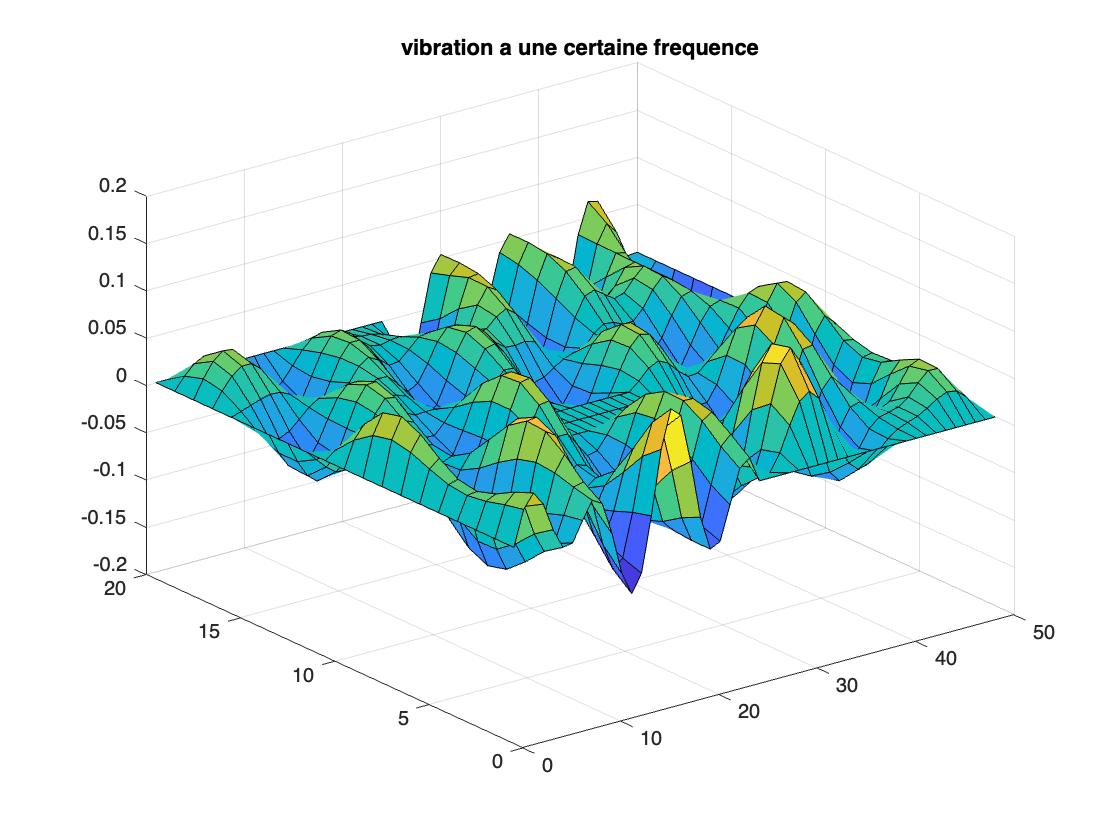

tambour();

Perso, je trouve que certaines vibrations look vraiment cursed (et donc pas physiquement plausibles), en particulier pour les basses fréquences qui correspondent à des eigenval égales à -1. Certaines ont des points très rapprochés qui ne semblent pas être liés (ça ressemble à des pics de hérisson / à des hérissements literally). En fait, tous les points qui étaient fixés au départ deviennent non-fixés (et donc sont les points où y'a des pics) et inversement. Maybe c'est juste parce que une des matrices à été mal initialisée (mais j'ai vérifié à peu près 69 fois), ou alors c'est parce qu'on a franchi des limites qui sont physiquement infranchissables (genre une fréquence négative). Bref, jsp :)

**Application 2**

Si on veut faire avec des matrices non carrées, on parle alors de valeurs singulières et non de eigenval. Mais cette partie est un bonus et grosse flemme :) Le sujet dit juste qu'on peut s'en servir notamment pour la compression d'image et ça a l'air interesting en vrai.